Key saving information:

% 0_swipeLtoR
% 1_closingpalm
% 2_openingpalm
% 3_swipeRtoL
% 4_twistfingerscw
% 5_twistfingersccw

%[class number]_[class name]_sample[sample number]

## Read mmWave Device Information

Start by declaring the location of the adc_data.bin, mmwave.json, and setup.json files are located. If the location is known, put them into the script, otherwise, there are helper functions to get the files as needed

%if the file locations are known, list them here

%for mac
data_path = '/Users/David/OneDrive - Duke University/Radar Security Project/Matlab Processing/Data Sets/hand_gesture_samples/9_gesture_recordings_revC';
gesture_name = '/swipe_left_to_right';
adc_sample = '/adc_data_20';
adc_data_file_name = strcat(data_path,gesture_name,adc_sample,'.bin');
mmwave_setup_json_file_name = strcat(data_path,'/mmWaveDevice_info/JSON/mmwave_configuration.mmwave.json');

%saving information
class_number_and_path = '0_swipeLtoR';
sample_number = strcat('_sample',adc_sample(end));
save_file_name = strcat('/',class_number_and_path,sample_number);
save_path = '/Users/David/OneDrive - Duke University/Radar Security Project/Matlab Processing/Data Sets/hand_gesture_samples/for ML training';
mat_file_name = strcat(save_path,gesture_name,'/mat files',save_file_name,'.mat');
image_file_name = strcat(save_path,gesture_name,'/image files',save_file_name,'.png');

% %for windows - gesture recognition
% data_path = 'C:\Users\Operator\OneDrive - Duke University\Radar Security Project\Matlab Processing\Data Sets\hand_gesture_samples\9_gesture_recordings_revC';
% gesture_name = '\swipe_right_to_left';
% adc_sample = '\adc_data_14';
% adc_data_file_name = strcat(data_path,gesture_name,adc_sample,'.bin');
% mmwave_setup_json_file_name = strcat(data_path,'\mmWaveDevice_info\JSON\mmwave_configuration.mmwave.json');
% 
% %saving information
% class_number_and_path = '3_swipeRtoL';
% sample_number = strcat('_sample',adc_sample(end));
% save_file_name = strcat('\',class_number_and_path,sample_number);
% save_path = 'C:\Users\Operator\OneDrive - Duke University\Radar Security Project\Matlab Processing\Data Sets\hand_gesture_samples\for ML training\run_2_clipped';
% mat_file_name = strcat(save_path,gesture_name,'\mat files',save_file_name,'.mat');
% image_file_name = strcat(save_path,gesture_name,'\image files',save_file_name,'.png');

% for windows - attacker_defender_configurations
% data_path = 'C:\Users\Operator\OneDrive - Duke University\Radar Security Project\Matlab Processing\Data Sets\attacker_defender_experiments_mar_4_2022\attack_7_2 attack chirp per defense chirp same slope_closer frames';
% adc_data_file_name = strcat(data_path,'\PostProc\adc_data.bin');
% mmwave_setup_json_file_name = strcat(data_path,'\JSON\mmwave_configuration.mmwave.json');


%otherwise use these helper functions
mmwave_json_file_name = GET_MMWAVE_SETUP_JSON_FILE(mmwave_setup_json_file_name);
adc_bin_file_name = GET_ADC_DATA_BIN_FILE(adc_data_file_name);

Next, instantiate a MMWaveDeviceClass which reads the mmwave.setup file to obtain all necessary information from the mmWave Device

mmWave_device = MMWaveDevice(adc_bin_file_name,mmwave_json_file_name);
%mmWave_device.printDeviceConfiguration();

## Generate ADC Data Cube

First, use the helper function to read the adc_data.bin file and sort the data into a continuous stream of samples for each LVDS lane (each Rx Channel)

raw_adc_data = READ_ADC_DATA_BIN_FILE(adc_bin_file_name,mmWave_device);

Next we generate the adc_data_cube which will be indexed as follows:

- adc_data_cube[rx channel, sample, chirp, frame]

num_frames = mmWave_device.num_frame;
chirps_per_frame = mmWave_device.num_chirp_per_frame;
rx_channels = mmWave_device.num_rx_chnl;
samples_per_chirp = mmWave_device.num_sample_per_chirp;


%generate an adc_data_cube
adc_data_cube = reshape(raw_adc_data,rx_channels,samples_per_chirp,chirps_per_frame,num_frames);


## Range FFT

### Calculate and plot range FFT for a single chirp

ranges = (0:mmWave_device.num_sample_per_chirp - 1) * mmWave_device.range_res;

### Generate 2D- FFT Plot

rx_channel = 1;
adc_channel_data_cube = reshape(adc_data_cube(rx_channel,:,:,:),samples_per_chirp,chirps_per_frame,num_frames);
fft_2d_range_cube = zeros(samples_per_chirp,chirps_per_frame,num_frames);

for frame_index = 1:num_frames
    fft_2d_range_cube(:,:,frame_index) = fft(adc_channel_data_cube(:,:,frame_index));
end

## Range-Doppler FFT

rx_channel = 1;
%adc_channel_data_cube = reshape(adc_data_cube(rx_channel,:,:,:),samples_per_chirp,chirps_per_frame,num_frames);
%fft_2d_range_cube = zeros(samples_per_chirp,chirps_per_frame,num_frames);

fft_range_doppler_cube = zeros(samples_per_chirp,chirps_per_frame,num_frames);

for frame_index = 1:num_frames
    fft_range_doppler_cube(:,:,frame_index) = fftshift(fft(fft_2d_range_cube(:,:,frame_index).').',2);
end

## Generating Microdopler Signatures

In the future I will use matlab's findpeaks() function to get the exact "range" of the peak

%get the range fft from the 1st chirp of the desired frame
desired_frame = 1;
desired_chirp = 1;
peak_threshold = 70;
frame_data = 20*log10(abs(fft_2d_range_cube(:,desired_chirp,desired_frame)));
[peaks,locations] = findpeaks(frame_data,...
                            "MinPeakHeight",peak_threshold, ...
                            "sortStr", 'descend');
%connect the peak location with a range
%peak_index = locations;
peak_ranges = ranges(locations);
potential_peak_ranges = peak_ranges(peak_ranges < 0.9 & peak_ranges > 0.6);
peak_index_guess = find(ranges == potential_peak_ranges(1))

peak_index_guess = 20

%next we look around our initial guess to determine the range with the
%greatest velocity (i.e: the best micro-doppler image)
search_width = 5;
velocity_peak_threshold = 105;

%initialize arrays to hold the max and min velocities for each range
max_velocity_indicies = zeros(1,2 * search_width + 1);
min_velocity_indicies = zeros(1,2 * search_width + 1);

%for each range in the search width
for i = 1 : 2 * search_width + 1
    range_index = peak_index_guess - search_width - 1 + i;

    %generate the micro doppler image
    micro_doppler_at_range = reshape(20*log10(abs(fft_range_doppler_cube(range_index,:,:))),chirps_per_frame,num_frames);
    max_velocity_indicies(i) = int32(chirps_per_frame/2);
    min_velocity_indicies(i) = int32(chirps_per_frame/2); 

    %go through each frame of velocity info and look for the max and min
    %velocity peak
    for frame = 1:num_frames
        [peaks,locations] = findpeaks(micro_doppler_at_range(:,frame), ...
                                            "MinPeakHeight",velocity_peak_threshold);
        %if higher than the current max or min for that particular range,
        %note it
        if(~isempty(peaks))
            if(locations(1) < min_velocity_indicies(i))
                min_velocity_indicies(i) = locations(1);
            end
            if(locations(end) > max_velocity_indicies(i))
                max_velocity_indicies(i) = locations(end);
            end
        end
    end
end


%see which of the ranges in the search region had the highest and lowest
%velocities
v_max = mmWave_device.v_max;
v_res = mmWave_device.v_res;
velocities = -v_max:v_res:(v_max-v_res);

max_velocities = velocities(max_velocity_indicies);
min_velocities = velocities(min_velocity_indicies);

[max_velocity,max_velocity_index] = max(max_velocities);
[min_velocity,min_velocity_index] = min(min_velocities);

if (max_velocity > abs(min_velocity))
    new_peak_guess = peak_index_guess - search_width - 1 + max_velocity_index;
else
    new_peak_guess = peak_index_guess - search_width - 1 + min_velocity_index;
end
new_peak_guess

new_peak_guess = 21

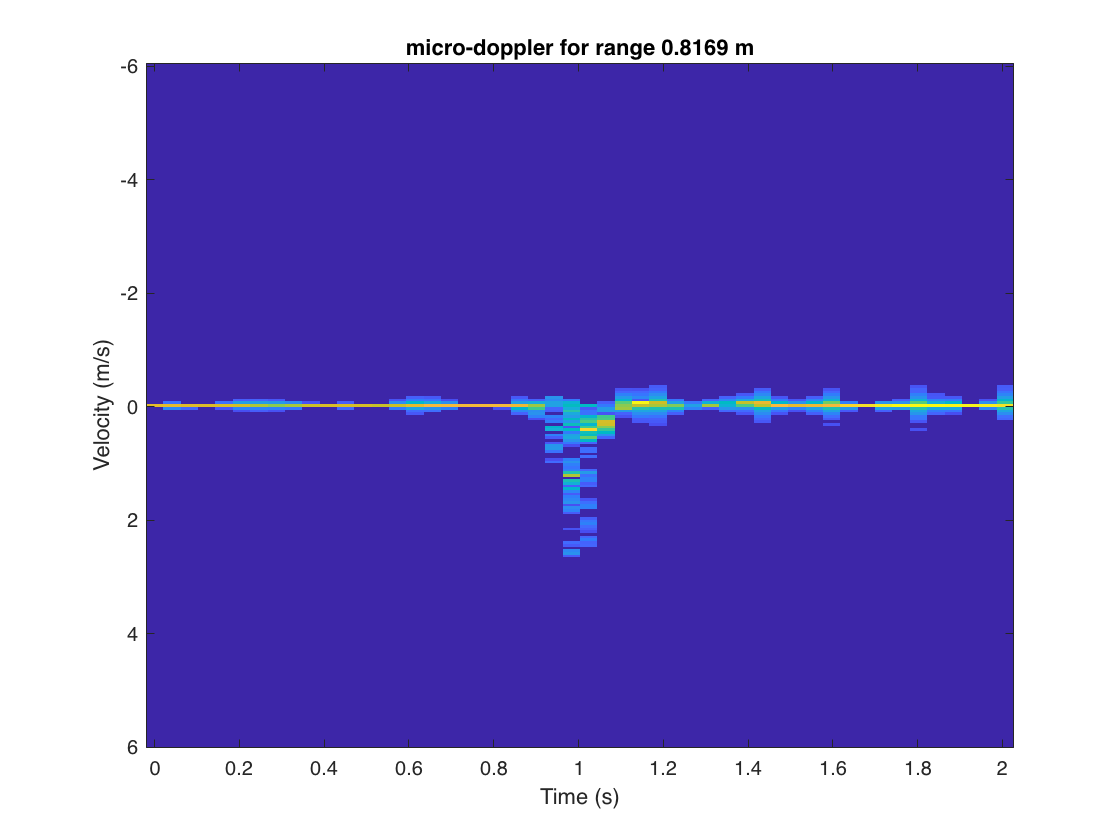

clf;
peak_index = 21;
%peak_index = new_peak_guess;

%next, get the micro-doppler signature from every frame at the specified
%distance
micro_doppler_at_range = reshape(20*log10(abs(fft_range_doppler_cube(peak_index,:,:))),chirps_per_frame,num_frames);
micro_doppler_at_range(micro_doppler_at_range < velocity_peak_threshold-5) = velocity_peak_threshold-10;

%finally generate a plot:
v_max = mmWave_device.v_max;
v_res = mmWave_device.v_res;
velocities = -v_max:v_res:(v_max-v_res);

frame_periodicity = mmWave_device.frame_periodicity * 1e-3;
times = 0:frame_periodicity:num_frames*frame_periodicity - frame_periodicity;

plot_title = sprintf('micro-doppler for range %0.4f m',ranges(peak_index));

imagesc(times,velocities, micro_doppler_at_range);
title(plot_title)
xlabel('Time (s)')
ylabel('Velocity (m/s)')


% surf(times,velocities, micro_doppler_at_range);
% title(plot_title)
% xlabel('time (s)')
% ylabel('Velocity (m/s)')
% zlabel('Magnitude (dB)')

Save the plot and .mat file for the micro_doppler_at_range data

save(mat_file_name,'micro_doppler_at_range');
saveas(gcf,image_file_name);
clf;